### Common paths

mainFolderPath = strcat('Z:\Projects\РФФИ-Норвегия\Данные\', ...
    'Экспериментальные данные в лаборатории\', ...
    'Droplet freezing facility data\Generating droplets\');
videoFolderPath = strcat(mainFolderPath, 'VIDEO_DATA\CROPPED_VIDEO\');
imgProcessingResFolderPath = strcat(mainFolderPath, 'IMAGE_PROCESSING_DATA\');
% cropping folder
croppingFolderPath = strcat(mainFolderPath, "VIDEO_DATA\cropping_data\");

procDataName = "image_processing.csv";
procDataPath = strcat(imgProcessingResFolderPath, procDataName);

toAnalyzeFile = "to_analyze.txt";
 
dataCell = splitlines(fileread(strcat(imgProcessingResFolderPath,toAnalyzeFile)));
testCount = length(dataCell);
disp(strcat("Count of analyzing tests: ", string(testCount)));

Count of analyzing tests: 14


### Load all needs videos

 
[allVideos, template, videoCount] = loadVideos(testCount, dataCell, videoFolderPath, croppingFolderPath);

14. Test #0277
Count of videos: 2
0277_template.jpg loaded
1) loading...
...loaded
2) loading...
...loaded
13. Test #0276
Count of videos: 2
0276_template.jpg loaded
1) loading...
...loaded
2) loading...
...loaded
12. Test #0275
Count of videos: 2
0275_template.jpg loaded
1) loading...
...loaded
2) loading...
...loaded
11. Test #0274
Count of videos: 1
0274_template.jpg loaded
1) loading...
...loaded
10. Test #0272
Count of videos: 3
0272_template.jpg loaded
1) loading...
...loaded
2) loading...
...loaded
3) loading...
...loaded
9. Test #0271
Count of videos: 2
0271_template.jpg loaded
1) loading...
...loaded
2) loading...
...loaded
8. Test #0270
Count of videos: 2
0270_template.jpg loaded
1) loading...
...loaded
2) loading...
...loaded
7. Test #0269
Count of videos: 2
0269_template.jpg loaded
1) loading...
...loaded
2) loading...
...loaded
6. Test #0268
Count of videos: 2
0268_template.jpg loaded
1) loading...
...loaded
2) loading...
...loaded
5. Test #0267
Count of videos: 2
0267_tem

#### Templates correction

newTemplate = cell(testCount,1);
noizeKoef = 0.6

noizeKoef = 0.6000

valueQuantile = 0.7

valueQuantile = 0.7000

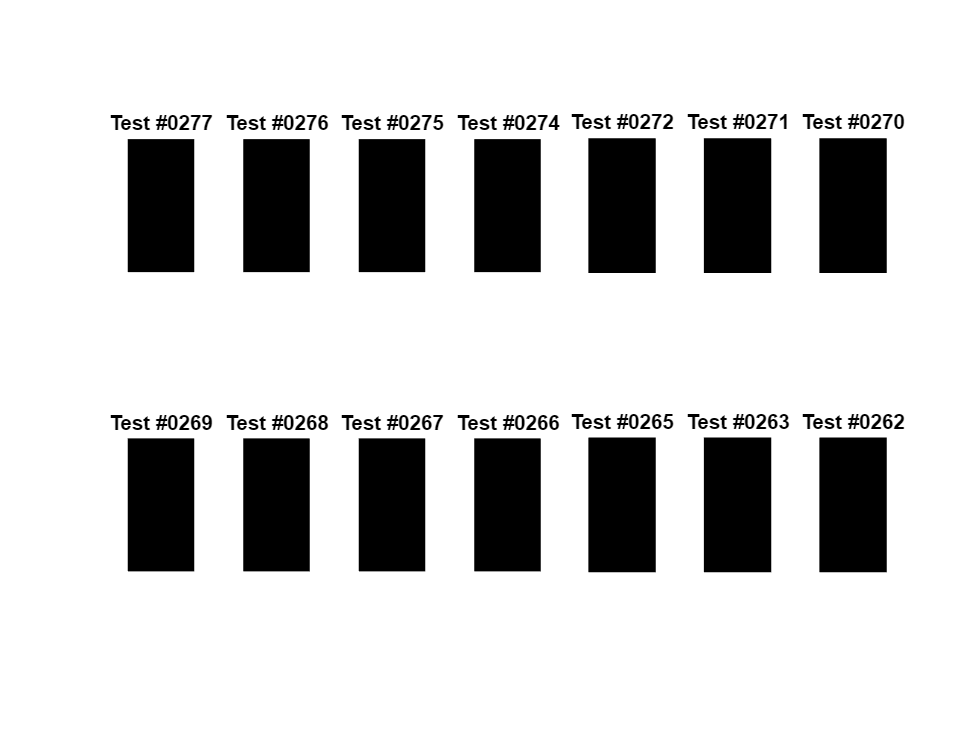

 
clf;
templTile = tiledlayout('flow','TileSpacing','tight');
parfor relTestNum = 1:testCount
    newTemplate{relTestNum} = correctTemplate(template{relTestNum},...
        noizeKoef,dataCell{relTestNum},valueQuantile);
end

## **Analyze frames**

**threshold - **grayscale value (1 to 256) for binarizing image (logical 1 if intensity > threshold);

**closeRadius** - disk radius of morphological structuring element for closing areas *(**low value** - droplets with morphological defects, **high value* - combines closing droplets*)*;

**minPixels** - max area of region for deliminating.

threshold = 50

threshold = 50

closeRadius = 15

closeRadius = 15

minPixels = 50

minPixels = 50

dropletsCountLimit = 4

dropletsCountLimit = 4

### Analyzing

testAnalyzingLimits = [1 inf]

testAnalyzingLimits =      1   Inf


needleOnFrame = false

needleOnFrame = logical
   0


1) TEST #0262
Crop #1
Estimated droplets count: 17
Flow type: Jet
Crop #2
Estimated droplets count: 19
Flow type: Jet
2) TEST #0263
Crop #1
Estimated droplets count: 1
Flow type: Single
Crop #2
Estimated droplets count: 1
Flow type: Single
Crop #3
Estimated droplets count: 1
Flow type: Single
3) TEST #0265
Crop #1
Estimated droplets count: 1
Flow type: Single
Crop #2
Estimated droplets count: 1
Flow type: Single
4) TEST #0266
Crop #1
Estimated droplets count: 2
Flow type: Multi
Crop #2
Estimated droplets count: 2
Flow type: Multi
5) TEST #0267
Crop #1
Estimated droplets count: 6
Flow type: Jet
Crop #2
Estimated droplets count: 6
Flow type: Jet
6) TEST #0268
Crop #1
Estimated droplets count: 18
Flow type: Jet
Crop #2
Estimated droplets count: 16
Flow type: Jet
7) TEST #0269
Crop #1
Estimated droplets count: 18
Flow type: Jet
Crop #2
Estimated droplets count: 17
Flow type: Jet
8) TEST #0270
Crop #1
Estimated droplets count: 19
Flow type: Jet
Crop #2
Estimated droplets count: 18
Flow type

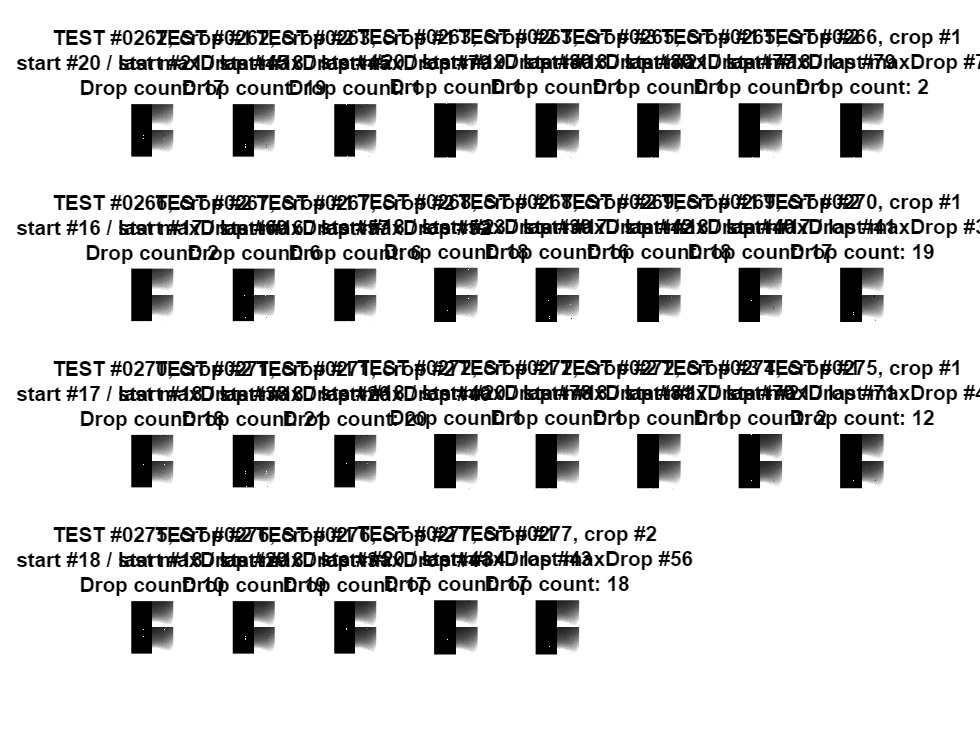

 
[analyzingRange, analyzedFrames, estimDropCount, flowType, allDropCount] =...
    analyzeTests(testAnalyzingLimits, testCount, videoCount, dataCell,...
    allVideos, newTemplate, threshold, closeRadius, minPixels,...
    dropletsCountLimit, needleOnFrame);

### Get droplets characteristics & save them

% IN LOOP -> imgprocT
 
analyzingTestCount = length(analyzedFrames)

analyzingTestCount = 14

1) TEST #0262


Crop #2


NOT Single flow type
NO Figure
NO values before
Saved row:
    test    crop    autoFlowType    autoDropCount    pixDiameter    sigmaPixDiameter    startingPixVelocity    endingPixVelocity
    ____    ____    ____________    _____________    ___________    ________________    ___________________    _________________

    262      2        {'Jet'}            19               0                0                     0                     0        

Crop #1


NOT Single flow type
NO Figure
NO values before
Saved row:
    test    crop    autoFlowType    autoDropCount    pixDiameter    sigmaPixDiameter    startingPixVelocity    endingPixVelocity
    ____    ____    ____________    _____________    ___________    ________________    ___________________    _________________

    262      1        {'Jet'}            17               0                0                     0                     0        



2) TEST #0263


Crop #3
First relative frame number, when droplet exists: 1
Last relative frame number, when droplet exists: 98
Average droplet's diameter, pixels: 43.2
Sigma of droplet's diameter, pixels: 2.5
Starting velocity, pixels per frame: 8.6
Ending velocity, pixels per frame: 33.8


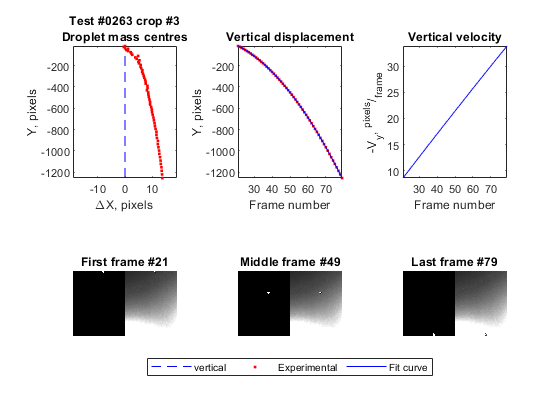

0263_imgproc_3 - saved
0263_pixprop_3 - saved
NO values before
Saved row:
    test    crop    autoFlowType    autoDropCount    pixDiameter    sigmaPixDiameter    startingPixVelocity    endingPixVelocity
    ____    ____    ____________    _____________    ___________    ________________    ___________________    _________________

    263      3       {'Single'}           1            43.218            2.4716               8.6044                33.824      

Crop #2
First relative frame number, when droplet exists: 1
Last relative frame number, when droplet exists: 98
Average droplet's diameter, pixels: 43.6
Sigma of droplet's diameter, pixels: 2.2
Starting velocity, pixels per frame: 8.6
Ending velocity, pixels per fr

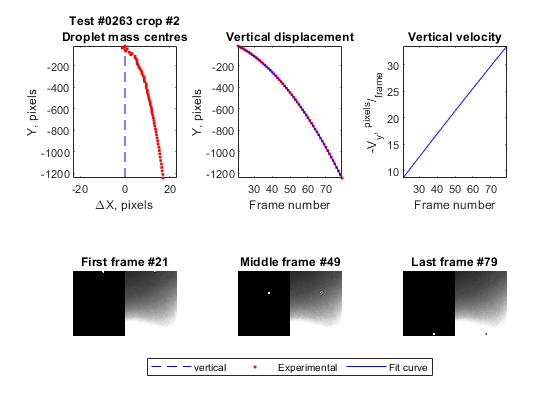

0263_imgproc_2 - saved
0263_pixprop_2 - saved
NO values before
Saved row:
    test    crop    autoFlowType    autoDropCount    pixDiameter    sigmaPixDiameter    startingPixVelocity    endingPixVelocity
    ____    ____    ____________    _____________    ___________    ________________    ___________________    _________________

    263      2       {'Single'}           1            43.569            2.2463               8.6049                33.552      

Crop #1
First relative frame number, when droplet exists: 1
Last relative frame number, when droplet exists: 97
Average droplet's diameter, pixels: 44.0
Sigma of droplet's diameter, pixels: 2.3
Starting velocity, pixels per frame: 8.6
Ending velocity, pixels per fr

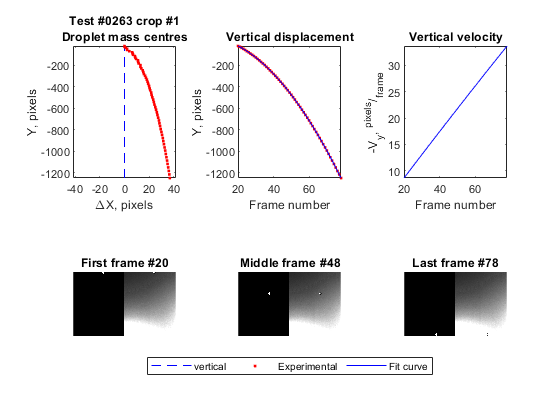

0263_imgproc_1 - saved
0263_pixprop_1 - saved
NO values before
Saved row:
    test    crop    autoFlowType    autoDropCount    pixDiameter    sigmaPixDiameter    startingPixVelocity    endingPixVelocity
    ____    ____    ____________    _____________    ___________    ________________    ___________________    _________________

    263      1       {'Single'}           1             43.99            2.2651                8.644                33.648      



3) TEST #0265


Crop #2
First relative frame number, when droplet exists: 1
Last relative frame number, when droplet exists: 98
Average droplet's diameter, pixels: 45.1
Sigma of droplet's diameter, pixels: 1.9
Starting velocity, pixels per frame: 11.2
Ending velocity, pixels per frame: 34.5


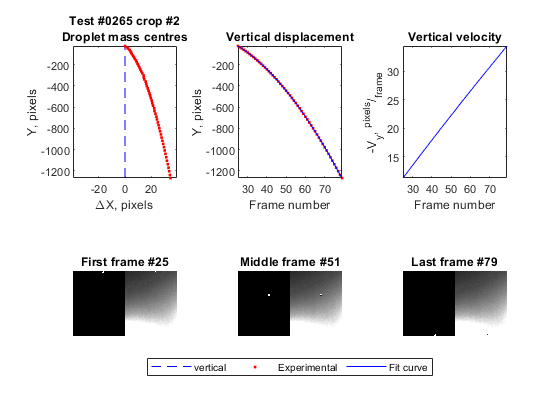

0265_imgproc_2 - saved
0265_pixprop_2 - saved
NO values before
Saved row:
    test    crop    autoFlowType    autoDropCount    pixDiameter    sigmaPixDiameter    startingPixVelocity    endingPixVelocity
    ____    ____    ____________    _____________    ___________    ________________    ___________________    _________________

    265      2       {'Single'}           1            45.074            1.8897               11.234                34.488      

Crop #1
First relative frame number, when droplet exists: 1
Last relative frame number, when droplet exists: 95
Average droplet's diameter, pixels: 45.2
Sigma of droplet's diameter, pixels: 1.9
Starting velocity, pixels per frame: 10.6
Ending velocity, pixels per f

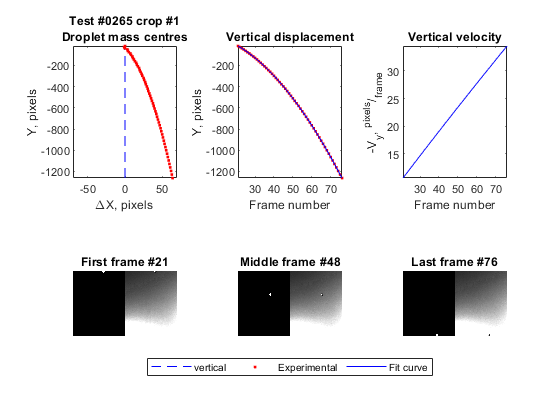

0265_imgproc_1 - saved
0265_pixprop_1 - saved
NO values before
Saved row:
    test    crop    autoFlowType    autoDropCount    pixDiameter    sigmaPixDiameter    startingPixVelocity    endingPixVelocity
    ____    ____    ____________    _____________    ___________    ________________    ___________________    _________________

    265      1       {'Single'}           1             45.15            1.9033               10.592                34.516      



4) TEST #0266


Crop #2


NOT Single flow type
NO Figure
NO values before
Saved row:
    test    crop    autoFlowType    autoDropCount    pixDiameter    sigmaPixDiameter    startingPixVelocity    endingPixVelocity
    ____    ____    ____________    _____________    ___________    ________________    ___________________    _________________

    266      2       {'Multi'}            2               0                0                     0                     0        

Crop #1


NOT Single flow type
NO Figure
NO values before
Saved row:
    test    crop    autoFlowType    autoDropCount    pixDiameter    sigmaPixDiameter    startingPixVelocity    endingPixVelocity
    ____    ____    ____________    _____________    ___________    ________________    ___________________    _________________

    266      1       {'Multi'}            2               0                0                     0                     0        



5) TEST #0267


Crop #2


NOT Single flow type
NO Figure
NO values before
Saved row:
    test    crop    autoFlowType    autoDropCount    pixDiameter    sigmaPixDiameter    startingPixVelocity    endingPixVelocity
    ____    ____    ____________    _____________    ___________    ________________    ___________________    _________________

    267      2        {'Jet'}             6               0                0                     0                     0        

Crop #1


NOT Single flow type
NO Figure
NO values before
Saved row:
    test    crop    autoFlowType    autoDropCount    pixDiameter    sigmaPixDiameter    startingPixVelocity    endingPixVelocity
    ____    ____    ____________    _____________    ___________    ________________    ___________________    _________________

    267      1        {'Jet'}             6               0                0                     0                     0        



6) TEST #0268


Crop #2


NOT Single flow type
NO Figure
NO values before
Saved row:
    test    crop    autoFlowType    autoDropCount    pixDiameter    sigmaPixDiameter    startingPixVelocity    endingPixVelocity
    ____    ____    ____________    _____________    ___________    ________________    ___________________    _________________

    268      2        {'Jet'}            16               0                0                     0                     0        

Crop #1


NOT Single flow type
NO Figure
NO values before
Saved row:
    test    crop    autoFlowType    autoDropCount    pixDiameter    sigmaPixDiameter    startingPixVelocity    endingPixVelocity
    ____    ____    ____________    _____________    ___________    ________________    ___________________    _________________

    268      1        {'Jet'}            18               0                0                     0                     0        



7) TEST #0269


Crop #2


NOT Single flow type
NO Figure
NO values before
Saved row:
    test    crop    autoFlowType    autoDropCount    pixDiameter    sigmaPixDiameter    startingPixVelocity    endingPixVelocity
    ____    ____    ____________    _____________    ___________    ________________    ___________________    _________________

    269      2        {'Jet'}            17               0                0                     0                     0        

Crop #1


NOT Single flow type
NO Figure
NO values before
Saved row:
    test    crop    autoFlowType    autoDropCount    pixDiameter    sigmaPixDiameter    startingPixVelocity    endingPixVelocity
    ____    ____    ____________    _____________    ___________    ________________    ___________________    _________________

    269      1        {'Jet'}            18               0                0                     0                     0        



8) TEST #0270


Crop #2


NOT Single flow type
NO Figure
NO values before
Saved row:
    test    crop    autoFlowType    autoDropCount    pixDiameter    sigmaPixDiameter    startingPixVelocity    endingPixVelocity
    ____    ____    ____________    _____________    ___________    ________________    ___________________    _________________

    270      2        {'Jet'}            18               0                0                     0                     0        

Crop #1


NOT Single flow type
NO Figure
NO values before
Saved row:
    test    crop    autoFlowType    autoDropCount    pixDiameter    sigmaPixDiameter    startingPixVelocity    endingPixVelocity
    ____    ____    ____________    _____________    ___________    ________________    ___________________    _________________

    270      1        {'Jet'}            19               0                0                     0                     0        



9) TEST #0271


Crop #2


NOT Single flow type
NO Figure
NO values before
Saved row:
    test    crop    autoFlowType    autoDropCount    pixDiameter    sigmaPixDiameter    startingPixVelocity    endingPixVelocity
    ____    ____    ____________    _____________    ___________    ________________    ___________________    _________________

    271      2        {'Jet'}            20               0                0                     0                     0        

Crop #1


NOT Single flow type
NO Figure
NO values before
Saved row:
    test    crop    autoFlowType    autoDropCount    pixDiameter    sigmaPixDiameter    startingPixVelocity    endingPixVelocity
    ____    ____    ____________    _____________    ___________    ________________    ___________________    _________________

    271      1        {'Jet'}            21               0                0                     0                     0        



10) TEST #0272


Crop #3
First relative frame number, when droplet exists: 1
Last relative frame number, when droplet exists: 97
Average droplet's diameter, pixels: 43.5
Sigma of droplet's diameter, pixels: 1.9
Starting velocity, pixels per frame: 9.7
Ending velocity, pixels per frame: 34.1


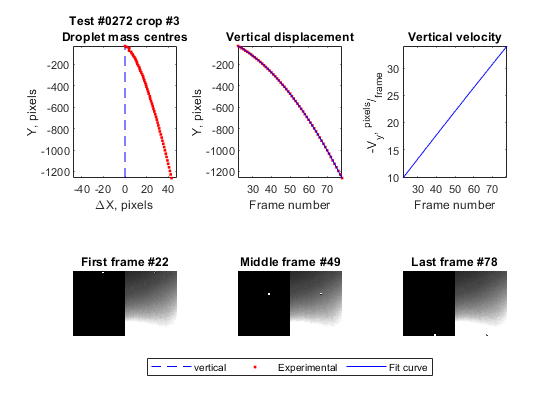

0272_imgproc_3 - saved
0272_pixprop_3 - saved
NO values before
Saved row:
    test    crop    autoFlowType    autoDropCount    pixDiameter    sigmaPixDiameter    startingPixVelocity    endingPixVelocity
    ____    ____    ____________    _____________    ___________    ________________    ___________________    _________________

    272      3       {'Single'}           1            43.528            1.907                9.7303                34.141      

Crop #2
First relative frame number, when droplet exists: 1
Last relative frame number, when droplet exists: 99
Average droplet's diameter, pixels: 44.2
Sigma of droplet's diameter, pixels: 1.9
Starting velocity, pixels per frame: 8.4
Ending velocity, pixels per fr

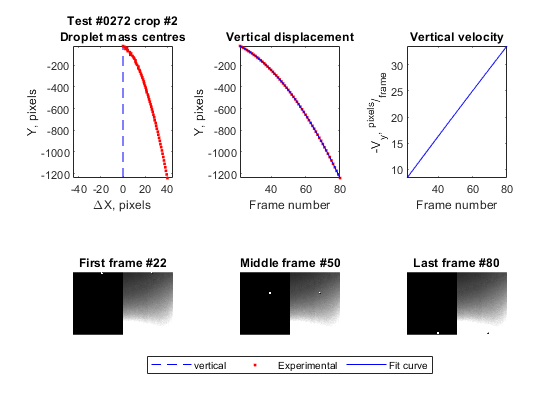

0272_imgproc_2 - saved
0272_pixprop_2 - saved
NO values before
Saved row:
    test    crop    autoFlowType    autoDropCount    pixDiameter    sigmaPixDiameter    startingPixVelocity    endingPixVelocity
    ____    ____    ____________    _____________    ___________    ________________    ___________________    _________________

    272      2       {'Single'}           1            44.243            1.8776                8.353                33.574      

Crop #1
First relative frame number, when droplet exists: 1
Last relative frame number, when droplet exists: 96
Average droplet's diameter, pixels: 44.3
Sigma of droplet's diameter, pixels: 1.5
Starting velocity, pixels per frame: 9.9
Ending velocity, pixels per fr

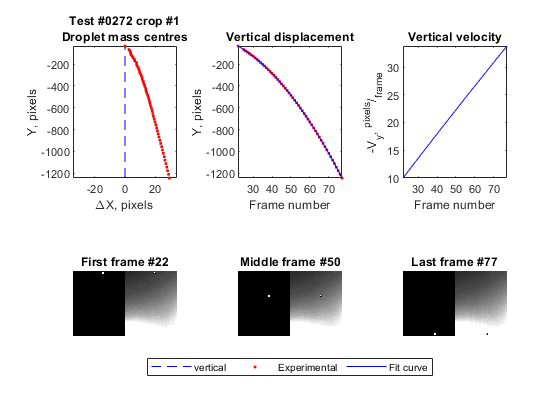

0272_imgproc_1 - saved
0272_pixprop_1 - saved
NO values before
Saved row:
    test    crop    autoFlowType    autoDropCount    pixDiameter    sigmaPixDiameter    startingPixVelocity    endingPixVelocity
    ____    ____    ____________    _____________    ___________    ________________    ___________________    _________________

    272      1       {'Single'}           1             44.26            1.4525               9.9414                33.801      



11) TEST #0274


Crop #1


NOT Single flow type
NO Figure
NO values before
Saved row:
    test    crop    autoFlowType    autoDropCount    pixDiameter    sigmaPixDiameter    startingPixVelocity    endingPixVelocity
    ____    ____    ____________    _____________    ___________    ________________    ___________________    _________________

    274      1       {'Multi'}            2               0                0                     0                     0        



12) TEST #0275


Crop #2


NOT Single flow type
NO Figure
NO values before
Saved row:
    test    crop    autoFlowType    autoDropCount    pixDiameter    sigmaPixDiameter    startingPixVelocity    endingPixVelocity
    ____    ____    ____________    _____________    ___________    ________________    ___________________    _________________

    275      2        {'Jet'}            10               0                0                     0                     0        

Crop #1


NOT Single flow type
NO Figure
NO values before
Saved row:
    test    crop    autoFlowType    autoDropCount    pixDiameter    sigmaPixDiameter    startingPixVelocity    endingPixVelocity
    ____    ____    ____________    _____________    ___________    ________________    ___________________    _________________

    275      1        {'Jet'}            12               0                0                     0                     0        



13) TEST #0276


Crop #2


NOT Single flow type
NO Figure
NO values before
Saved row:
    test    crop    autoFlowType    autoDropCount    pixDiameter    sigmaPixDiameter    startingPixVelocity    endingPixVelocity
    ____    ____    ____________    _____________    ___________    ________________    ___________________    _________________

    276      2        {'Jet'}            17               0                0                     0                     0        

Crop #1


NOT Single flow type
NO Figure
NO values before
Saved row:
    test    crop    autoFlowType    autoDropCount    pixDiameter    sigmaPixDiameter    startingPixVelocity    endingPixVelocity
    ____    ____    ____________    _____________    ___________    ________________    ___________________    _________________

    276      1        {'Jet'}            19               0                0                     0                     0        



14) TEST #0277


Crop #2


NOT Single flow type
NO Figure
NO values before
Saved row:
    test    crop    autoFlowType    autoDropCount    pixDiameter    sigmaPixDiameter    startingPixVelocity    endingPixVelocity
    ____    ____    ____________    _____________    ___________    ________________    ___________________    _________________

    277      2        {'Jet'}            18               0                0                     0                     0        

Crop #1


NOT Single flow type
NO Figure
NO values before
Saved row:
    test    crop    autoFlowType    autoDropCount    pixDiameter    sigmaPixDiameter    startingPixVelocity    endingPixVelocity
    ____    ____    ____________    _____________    ___________    ________________    ___________________    _________________

    277      1        {'Jet'}            17               0                0                     0                     0        



for relTestNum = 1:analyzingTestCount
    strTestNum = dataCell{analyzingRange(relTestNum)};
    testNum = uint16(str2double(strTestNum));
    disp(strcat(string(relTestNum),") TEST #",...
        strTestNum));
    cropCount = length(analyzedFrames{relTestNum});
    parfor numRange = 1:cropCount
        disp(strcat("Crop #", string(numRange)));
        figTitle = strcat('Test #',strTestNum,' crop #',string(numRange));
        curFig = figure;
        [propT, dropDiameter, fitYvelocity] =...
            postAnalyzeFrames(analyzedFrames{relTestNum}{numRange},...
            estimDropCount{relTestNum}(numRange), curFig, figTitle);

        if estimDropCount{relTestNum}(numRange) ~= 1
            disp("NOT Single flow type");
            disp("NO Figure");
        else
            figName = strcat(strTestNum,'_imgproc_',string(numRange));
            fullFigName = strcat(imgProcessingResFolderPath,...
                figName, '.fig');
            savefig(fullFigName);
            disp(strcat(figName, " - saved"));

            % SAVE TABLE-Values
            propTName = strcat(strTestNum,'_pixprop_',string(numRange));
            fullTName = strcat(imgProcessingResFolderPath, propTName, '.csv');
            writetable(propT,fullTName);
            disp(strcat(propTName, " - saved"));
        end

        % SAVE VALUES
        % LOAD IMAGE PROCESSING TABLE
        imgprocT = readtable(procDataPath);
        % IF NOT SINGLE - save only flowType & estimDropCount (others = 0 automatically)
        toShow = (imgprocT.test == testNum)&(imgprocT.crop == numRange);
        lastRes = imgprocT(toShow,:);
        if height(lastRes)>0
            disp("Last values:")
            lastRes = imgprocT(toShow,:);
            disp(lastRes);
        else
            disp("NO values before")
        end
        
        % delete previos ranges
        toDelete = toShow;
        imgprocT(toDelete,:) = [];
        
        % add new value
        savedRow = {testNum,numRange,flowType{relTestNum}{numRange},...
            estimDropCount{relTestNum}(numRange),...
            dropDiameter(1),dropDiameter(2),...
            fitYvelocity(1),fitYvelocity(2)};
        imgprocT = [imgprocT;savedRow];
        
        % WRITE TABLE
        writetable(imgprocT,procDataPath);
        
        disp('Saved row:')
        toShow = (imgprocT.test == testNum)&(imgprocT.crop == numRange);
        newRes = imgprocT(toShow,:);
        disp(newRes);

    end

end